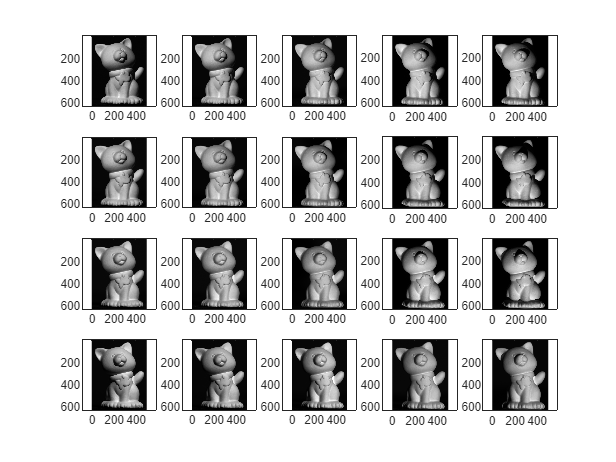

num_images = 20;
images = cell(num_images, 1);
for i = 1:num_images
    s = int2str(i);
    if i < 10
        s = "0" + s;
    end
    images{i} = imread("PSData/cat/Objects/Image_" + s + ".png");

    subplot(4, 5, i);
    imagesc(images{i});
    colormap gray;
    axis equal;
end

sz = size(images{1});

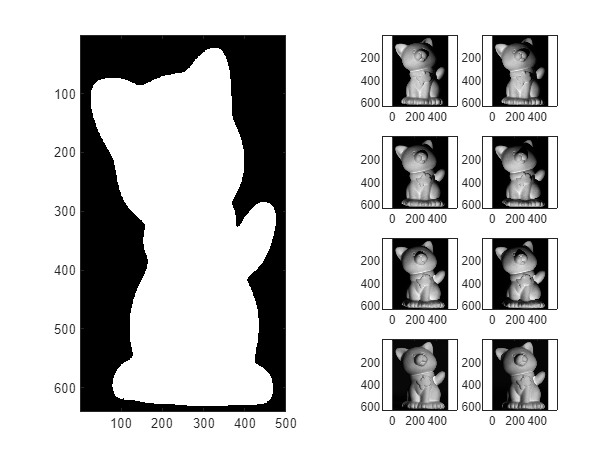

mask = zeros(sz);
threshold = 30;
for i = 1:num_images
    mask = mask | images{i} > threshold;
end
subplot(1, 2, 1);
imagesc(mask);
colormap gray;

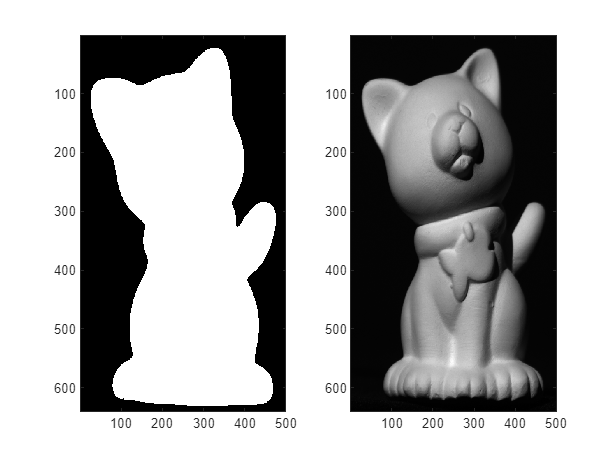

subplot(1, 2, 2);
imagesc(images{1});
colormap gray;

p = nnz(mask);
I = zeros(p, num_images);
for i = 1:num_images
    I(:,i) = images{i}(mask);
end

[U, Sigma, V] = svd(I, 'econ');
V = V';
U_prime = U(:, 1:3);
Sigma_prime = Sigma(1:3, 1:3);
V_prime = V(1:3, :);

Sigma_root = Sigma_prime .^ 0.5;
S_hat = U_prime * Sigma_root;
L_hat = Sigma_root * V_prime;
norm(S_hat * L_hat - I, 'fro') / norm(I, "fro")

ans = 0.0537

% Upgrade
coeff = [S_hat(:, 1) .^ 2, 2 * S_hat(:, 1) .* S_hat(:, 2), 2 * S_hat(:, 1) .* S_hat(:, 3), ...
    S_hat(:, 2) .^ 2, 2 * S_hat(:, 2) .* S_hat(:, 3), S_hat(:, 3) .^ 2];

B_nums = coeff \ ones(p, 1);
B = [B_nums(1), B_nums(2), B_nums(3)
    B_nums(2), B_nums(4), B_nums(5)
    B_nums(3), B_nums(5), B_nums(6)];

[W, Pi, ~] = svd(B);
A = W * Pi .^ 0.5;
S = S_hat * A;
L = A \ L_hat;

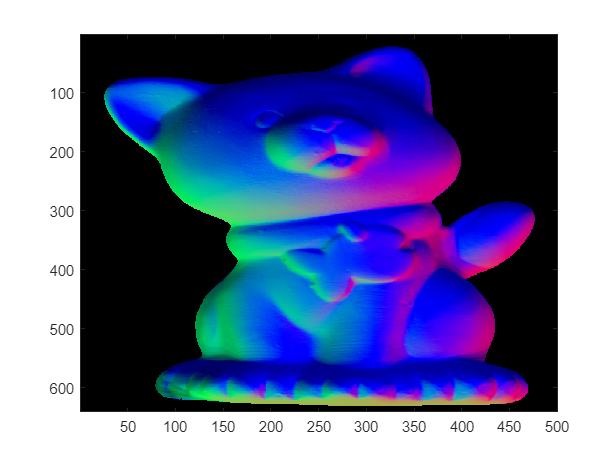

% Visualize
normals = normalize(S, 2, "norm");
normal_image = zeros(sz(1), sz(2), 3);

mask_3d = cat(3, mask, mask, mask);
normal_image(mask_3d) = normals;
normal_colors = (normal_image) .* mask_3d;

figure
imagesc(normal_colors);

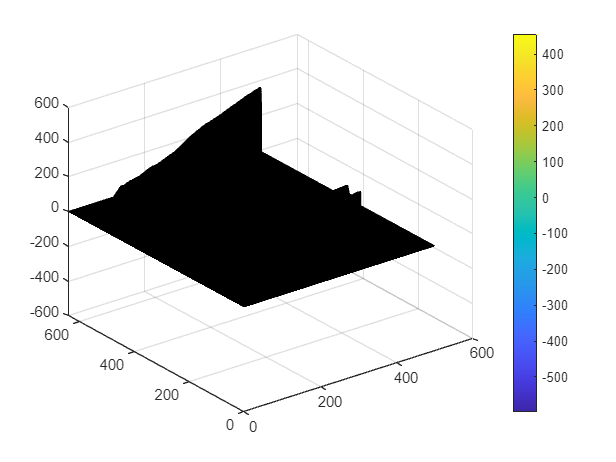

% Interate surface
depths = zeros(sz);
for row = 1:sz(1)
   for col = 2:sz(2)
       if mask(row, col) && mask(row, col-1)
           n = normalize(normal_image(row, col-1, :) + normal_image(row, col, :), 3, 'norm');
           if n(3) == 0
               n(3) = 1;
           end
           depths(row, col) = depths(row, col-1) - n(1) / n(3);
       end
   end
end
%for col = 1:sz(2)
%    for row = 2:sz(1)
%        if mask(row, col) && mask(row-1, col)
%            depths(row, col) = depths(row-1, col) - normal_image(row-1, col, 2) / normal_image(row-1, col, 3);
%        end
%    end
%end


surf(depths);
colorbar;

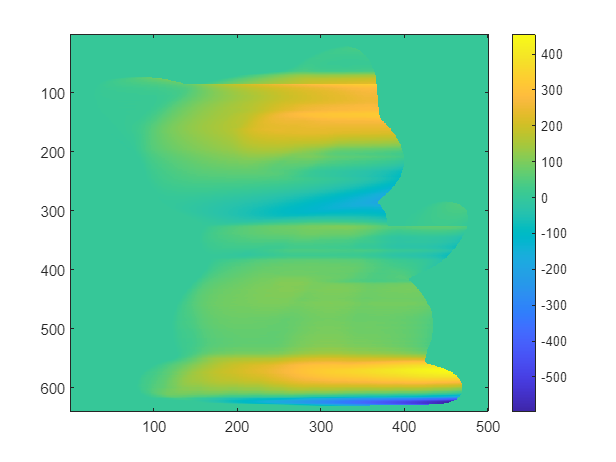

figure
imagesc(depths);
colorbar